# Set Page Margins in a Word Report

This example shows how to define page margins in a Word(DOCX) report. You can define top, bottom, left, right margins for a DOCX page, plus its header, footer and gutter sizes.

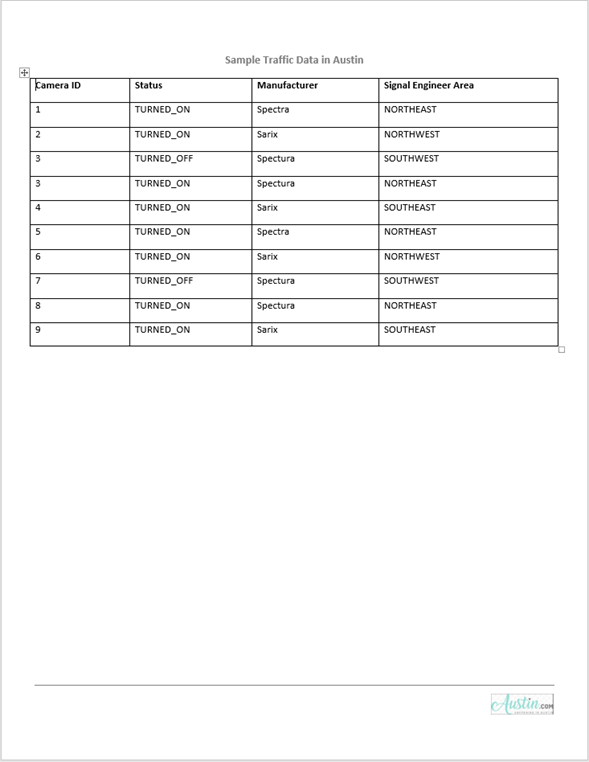

## Create Report

Import the DOM API packages so you do not have to use long, fully-qualified class names.

import mlreportgen.dom.*;

Create and open a report.

d = Document('myreport', 'docx');
open(d);

## Create DOCX Page Header

Get the current page layout object.

currentLayout = d.CurrentPageLayout;

Create a page header definition for DOCX document.

docxheader = DOCXPageHeader();

Create a DOM `Paragraph` object and make it center aligned and bold. Set its font size to 12pt. Append it to the `DOCXPageHeader` object.

p = Paragraph('Sample Traffic Data in Austin');
p.Style = [p.Style, {HAlign('center'), Bold(true), FontSize('12pt')}];
append(docxheader, p);

Assign the created `docxheader` object to the `PageHeaders` of the current page layout.

currentLayout.PageHeaders = docxheader;

## Create Body Content

Create cell arrays for the styles to be used by the formal table and its table entries.

dataTableStyle = {Border('solid'), ColSep('solid'), RowSep('solid'), Width('100%')...
    OuterMargin('0pt', '0pt', '0pt', '0pt')};

Create some sample data from the Austin traffic camera to include in the table. Then create a `FormalTable` object and include the sample data in the Header and Body sections.

dataHeader = {'Camera ID', 'Status', 'Manufacturer', 'Signal Engineer Area'};
dataBody = {'1', 'TURNED_ON', 'Spectra', 'NORTHEAST';
    '2', 'TURNED_ON', 'Sarix', 'NORTHWEST';
    '3', 'TURNED_OFF', 'Spectura', 'SOUTHWEST';
    '3', 'TURNED_ON', 'Spectura', 'NORTHEAST';
    '4', 'TURNED_ON', 'Sarix', 'SOUTHEAST';
    '5', 'TURNED_ON', 'Spectra', 'NORTHEAST';
    '6', 'TURNED_ON', 'Sarix', 'NORTHWEST';
    '7', 'TURNED_OFF', 'Spectura', 'SOUTHWEST';
    '8', 'TURNED_ON', 'Spectura', 'NORTHEAST';
    '9', 'TURNED_ON', 'Sarix', 'SOUTHEAST'};
dataTable = FormalTable(dataHeader, dataBody);
dataTable.Header.Style = [dataTable.Header.Style {Bold}];
dataTable.Style = [dataTable.Style dataTableStyle];
append(d, dataTable);

## Set Top Margin and Header Size

The `Top` property of the `PageMargins` object specifies the height of the margin. The `Header` property specifies the distance from the top of the page to the start of the header. The distance from the top of the page to the page body depends on the `Top` property, `Header` property and the height of the header content. For example, if the `Header` property is less than the `Top` property, the header starts in the top margin and expands downward to accommodate the header content. The body begins at the bottom of the margin or the header, which ever is greater.

Use the following settings to ensure that the header fits into the `Top` margin. Set the `Top` property to 1 inch. 1 inch equals 72 points, so 0.25 inches equals 18 pts. Set the `Header` value to 0.75 inches as remaining 0.25 inches is enough to accommodate the 12 pts `Paragraph` created in the DOCX Header. 

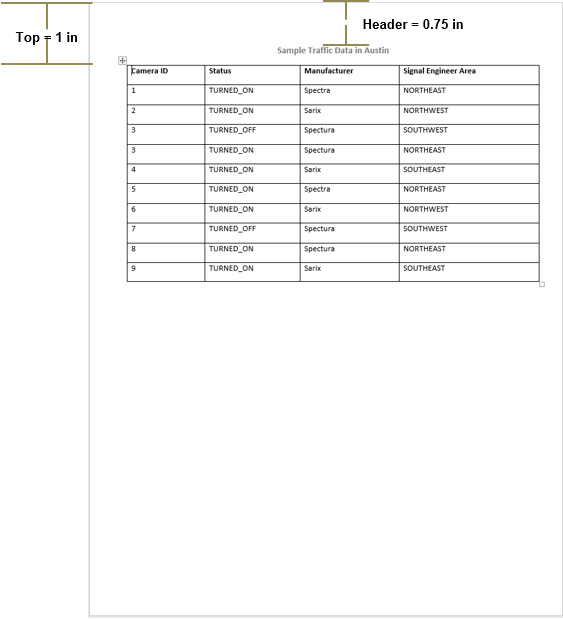

currentLayout.PageMargins.Top = '1in';
currentLayout.PageMargins.Header = '0.75in';

## Create DOCX Page Footer

Create a page footer definition for the DOCX document.

docxfooter = DOCXPageFooter();

Append a horizontal rule to the `docxfooter` object.

append(docxfooter, HorizontalRule());

Append an image to the `docxfooter` object. Use the DOM `ScaleToFit` format to scale the image to fit in the page. Assign the created `docxfooter` object to the `PageFooters` of the current page layout..

imgStyle = {ScaleToFit(true), HAlign('right'), Height('0.30in')};
img = Image('Logo_footer.Png');
img.Style = imgStyle;
append(docxfooter, img);
currentLayout.PageFooters = docxfooter;

## Set Bottom Margin and Footer Size

The `Bottom` property of the `PageMargins` object specifies the height of the page margin. The `Footer` property specifies the distance from the bottom of the page to the bottom of the footer. The distance from the bottom of the page to the page body depends on the settings of the `Bottom` and `Footer` properties and the height of the footer content. For example, if the `Footer` property is less than the `Bottom` property, the footer starts in the bottom margin and expands upward to expand the footer content. The body starts at the top of the margin or the footer, whichever is greater.

Set the `Bottom` property value to 1 inch. To accommodate the 0.30 high `Image` and the horizontal rule created in DOCX Footer, set the `Footer` property value to 0.5 inches. 

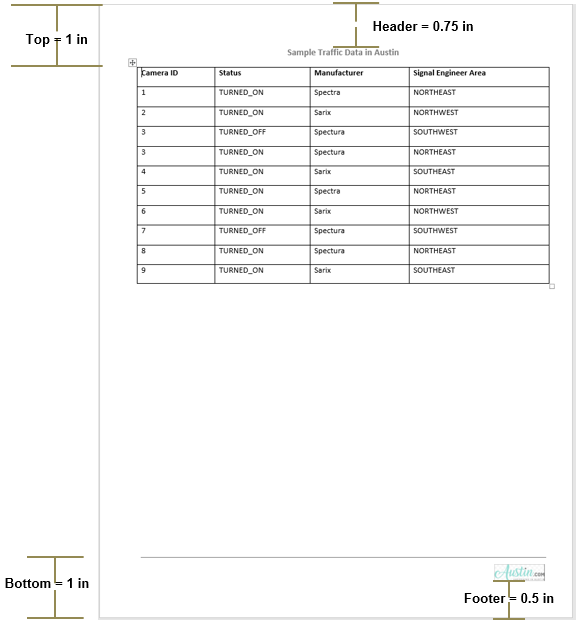

currentLayout.PageMargins.Bottom = '1in';
currentLayout.PageMargins.Footer = '0.5in';

## Set Left Margin, Right Margin and Gutter Size

This example uses the `Gutter` setting to leave room on the left side of the page for binding the report`. The Gutter` size is set to 0.25 inches and `Left` margin is set to 0.5 inches. So, the content starts from 0.75 inches(left margin + gutter) from the left side of the page. The `Right` margin is set to 0.5 inches.

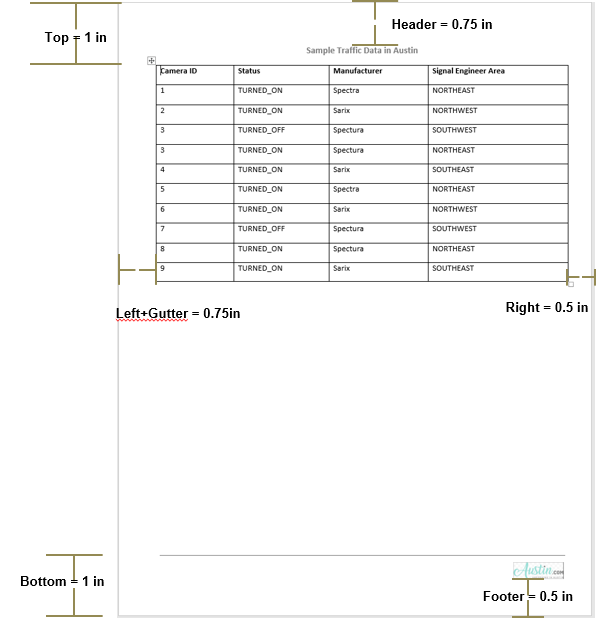

currentLayout.PageMargins.Gutter = '0.25in';
currentLayout.PageMargins.Left = '0.5in';
currentLayout.PageMargins.Right = '0.5in';

Generate and display the report.

close(d);
rptview(d.OutputPath);

*Copyright 2019 The MathWorks, Inc.*